clearvars

# Wind tunnel model 

u1 : flow control, u2 : temperature control

y1 : flow measure, y2 : temperature measure

## Identified model

% H= % Put here the model you found in seance 1

% H1: ventilation and flow u1 and y1 
H1 = tf([1.053,1.155],[1,1.942,6.112,1.517],'InputDelay',0.1);

% H2: chauffage and flow u2 and y1
H2 = 0;

% H3: ventilation and temperature u1 and y2
H3 = tf([-0.005487,0.02488,0.0264],[1,0.7964,0.1684],'InputDelay',1.7);

% H4: chauffage and temperature u2 and y2
H4 = tf([1.347,0.8525],[1,5.102,9.509,3.071],'InputDelay',0.05);

H = [H1, H2;H3, H4];

# Control model (discrete state space)

choice of a sampling period (keep the notation Te)

Te = 0.05;

% Matlab function to discretize a system
Hd = c2d(H,Te);

Change to state form, and state matrices extraction.

sysd=ss(Hd)

sysd =
 
  A = 
           x1      x2      x3      x4      x5      x6      x7      x8
   x1   2.893    -1.4  0.9075       0       0       0       0       0
   x2       2       0       0       0       0       0       0       0
   x3       0     0.5       0       0       0       0       0       0
   x4       0       0       0   1.961  -0.961       0       0       0
   x5       0       0       0       1       0       0       0       0
   x6       0       0       0       0       0   2.754  -1.264  0.7748
   x7       0       0       0       0       0       2       0       0
   x8       0       0       0       0       0       0     0.5       0
 
  B = 
           u1      u2
   x1  0.0625       0
   x2       0       0
   x3       0       0
   x4  0.0625       0
   x5       0       0
   x6       0  0.0625
   x7       0       0
   x8       0       0
 
  C = 
               x1          x2          x3          x4          x5          x6          x7          x8
   y1     0.02074   0.0004082    -0.

A=sysd.A

A =     2.8928   -1.4002    0.9075         0         0         0         0         0
    2.0000         0         0         0         0         0         0         0
         0    0.5000         0         0         0         0         0         0
         0         0         0    1.9605   -0.9610         0         0         0
         0         0         0    1.0000         0         0         0         0
         0         0         0         0         0    2.7537   -1.2644    0.7748
         0         0         0         0         0    2.0000         0         0
         0         0         0         0         0         0    0.5000         0


B=sysd.B

B =     0.0625         0
         0         0
         0         0
    0.0625         0
         0         0
         0    0.0625
         0         0
         0         0


C=sysd.C

C =     0.0207    0.0004   -0.0194         0         0         0         0         0
         0         0         0    0.0235   -0.0224    0.0250   -0.0005   -0.0225


D=sysd.D

D =          0         0
   -0.0055         0


#### Inclusion of operating points

Inclusion of operating points : ${u}_0(k+1)=u_{0}(k)
$ et $y_0(k+1)=y_0(k)$ 

Aa= [A, -B, zeros(8,2); zeros(2,8), eye(2,2), zeros(2,2); zeros(2,10), eye(2,2)];
Ba= [B; zeros(2,2); zeros(2,2)];
Ca= [C, zeros(2,2), eye(2,2)];

#### Decomposition according to observability

Obsa=obsv(Aa,Ca);
rank(Obsa);
% rank is 10;

There are xx observable modes 

[AO,BO,CO,TO,k]=obsvf(Aa,Ba,Ca);

$T0$  is the basis change matrix (useful for Simulink later)

We get only the observable part

Ao=AO(3:12,3:12);
Bo=BO(3:12,1:2);
Co=CO(1:2,3:12);

Eigenvalues study

eig(Ao)

ans =    0.8868 + 0.0643i
   0.8868 - 0.0643i
   0.9803 + 0.0049i
   0.9803 - 0.0049i
   0.9800 + 0.0000i
   0.9531 + 0.1066i
   0.9531 - 0.1066i
   0.9867 + 0.0000i
   1.0000 + 0.0000i
   1.0000 + 0.0000i


## State observer

Choice of the poles:

poles_obs= eig(Ao);

Matrice determination

L0 = place(Ao',Co',poles_obs);
L0 = L0';
eig(Ao-L0*Co);

State model of the observer (keep the following notations for simulink)

A_OBS= Ao - L0*Co;
B_OBS= [Bo, L0];
C_OBS= eye(rank(Obsa));
D_OBS= zeros(rank(Obsa), 4);

# Prediction model

Choice of the size of the prediction model

Np=30; % keep the notation Np (required for simulink)

Explicite matrices definition

We want the following model $Y(K+1|k)=Fx(k|k)+HU(K|k)$ 

nx=size(Co*Ao,1); 
% the row number
nc=size(Ao,1);
nu=size(Co*Bo,2);

F=zeros(Np*nx,nc);
H=zeros(Np*nx,Np*nu);

for i=1:Np
    F(nx*(i-1)+1:nx*i,:)=Co*(Ao^i) ;
    for j=1:i
        H(nx*(i-1)+1:nx*i,nu*(j-1)+1:nu*j)=Co*(Ao^(i-j))*Bo;
    end
end

Unitary tests

% 

# Problem construction: energy minimization, under maximum power constraint.

#### Initial conditions:

y1min = 0;
y1max = 10000;
y2min = 0.1; 
y2max = y2min + 2;
Ymin = repmat([y1min;y2min],Np,1);
Ymax = repmat(y2max,Np,1);

UTOTmax = 2*ones(Np,1);

Nsimu=100;
% u1:flow control; 
% u2:temperature control 

#### Cost function:

1/2 (Y - Ymin)^T (Y - Ymin) + lamda/2 U^T U 

#### Constraints :

lamda_1 = 0.1;
lamda_2 = 0.05;
W = [eye(2*Np), zeros(2*Np,5*Np); zeros(2*Np), lamda_1*eye(2*Np), zeros(2*Np,3*Np); zeros(3*Np,4*Np), lamda_2*eye(3*Np)];
f = [-Ymin', zeros(1,5*Np)];

T = zeros(Np,2*Np);
for i = 1:Np
    T(i,2*i-1:2*i) = [1,1];
end

P = zeros(Np,2*Np);
for i = 1:Np
    P(i,2*i) = 1;
end

Q = zeros(2*Np,3*Np);
for i = 1:Np
    Q(2*i-1,3*i-2) = 1;
    Q(2*i,3*i-1) = 1;
end

R = zeros(Np,3*Np);
for i = 1:Np
    R(i,3*i) = 1;
end

A_quad = [zeros(Np,2*Np), T, zeros(Np,3*Np); -eye(2*Np), zeros(2*Np), -Q; P, zeros(Np,2*Np), -R];
b_quad = [UTOTmax; -Ymin; P*Ymin + 2*ones(Np,1)];

Aeq = [eye(2*Np), -H, zeros(2*Np,3*Np)];

#### Optimisation problem resolution

#### open loop model validation

xinit=0*ones(10,1);
xk=xinit;
X = [];
U = [];

for i=1:Nsimu
    X = [X xk];
    beq = F*xk;
    [Uopt] = quadprog(W,f,A_quad,b_quad,Aeq,beq,[],[]);
    uk=Uopt(2*Np+1:2*Np+2,1); %optimal control U
    U = [U,uk];
    xkp1=Ao*xk+Bo*uk;
    xk=xkp1;
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

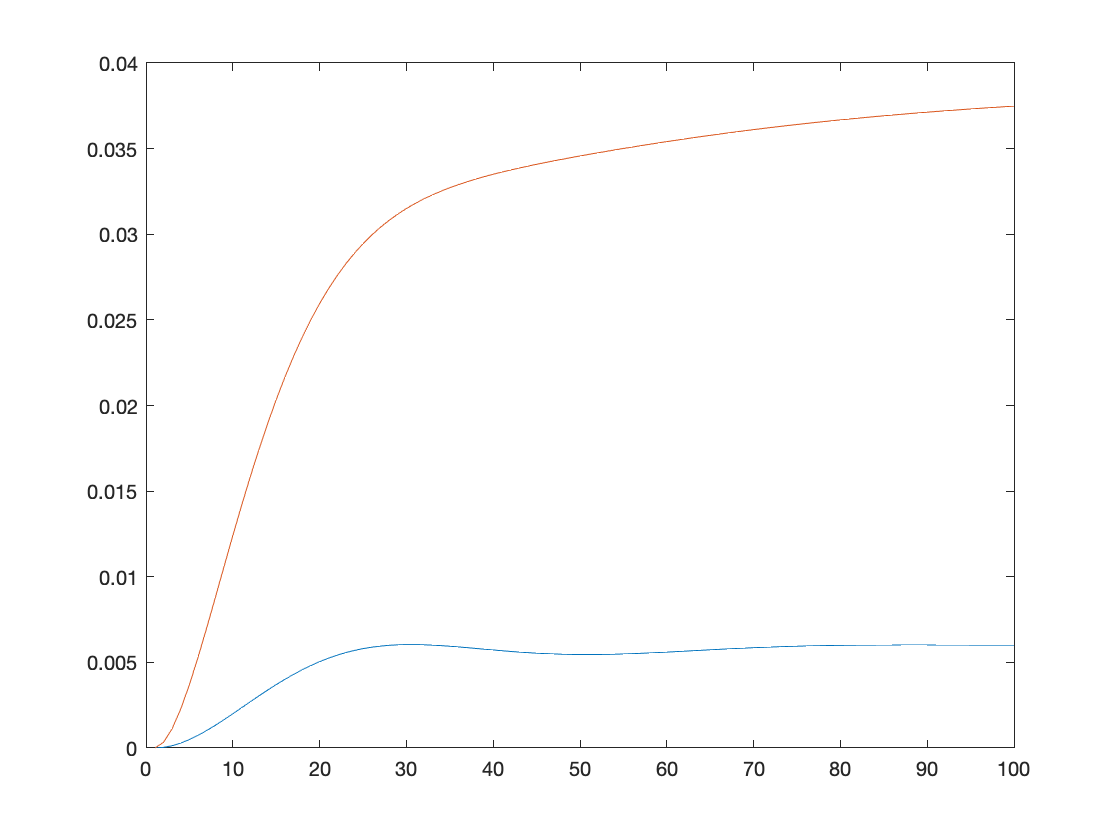

Y_obs = Co*X;
plot(1:Nsimu,Y_obs)

U_tot = U(1,:)+U(2,:)

U_tot =     0.2066    0.2025    0.1986    0.1948    0.1912    0.1878    0.1847    0.1818    0.1791    0.1766    0.1744    0.1724    0.1706    0.1689    0.1675    0.1662    0.1650    0.1640    0.1631    0.1623    0.1616    0.1610    0.1605    0.1600    0.1596    0.1592    0.1588    0.1585    0.1582    0.1579    0.1576    0.1573    0.1570    0.1568    0.1565    0.1562    0.1560    0.1557    0.1554    0.1551    0.1548    0.1546    0.1543    0.1540    0.1537    0.1534    0.1531    0.1528    0.1526    0.1523


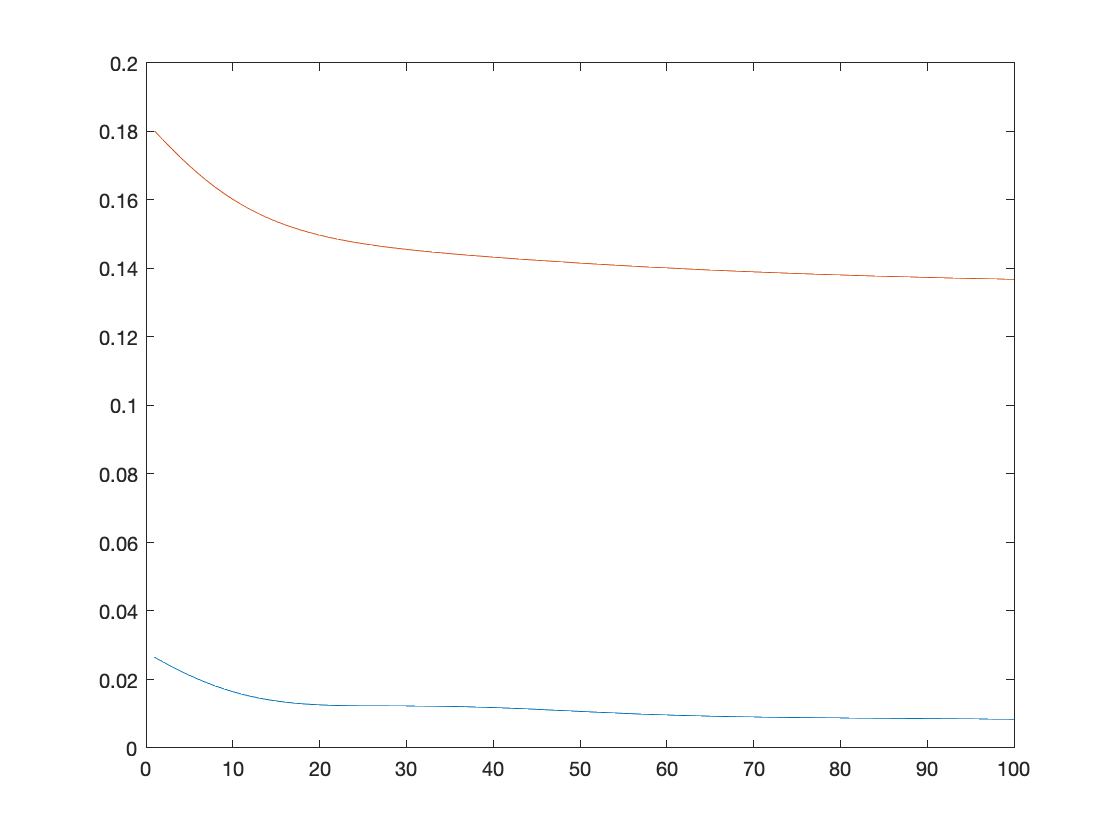

plot(1:Nsimu,U)

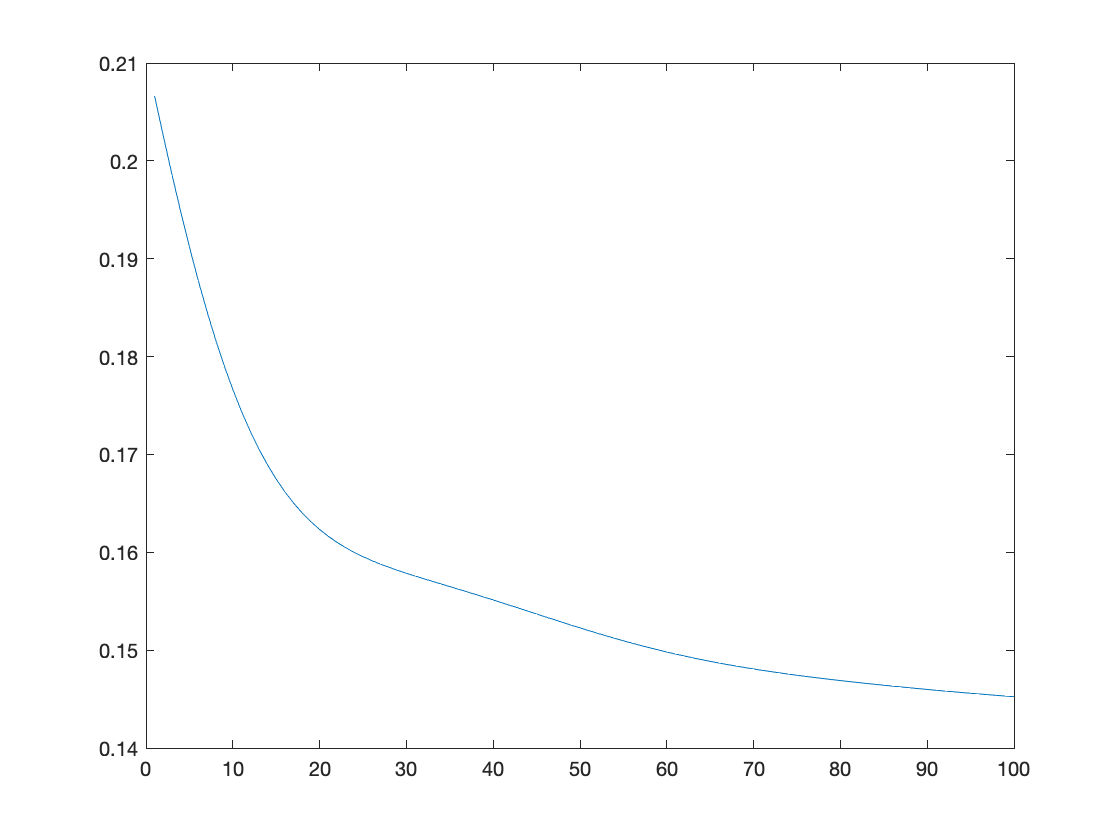

plot(1:Nsimu,U_tot)

# Application into Simulink

Ouvrir et compléter le simulink ('2A_SG8_MPC_simu_MPC_student.slx'). 

You must also compile the following two sections for the Simulink file to be executable.

#### Umax prediction generator

Amaxpred=zeros(Np,Np);
Amaxpred(1:Np-1,2:Np)=eye((Np-1));
Bmaxpred=zeros(Np,1);
Bmaxpred(Np,1)=eye(1);
Cmaxpred=eye(Np);
Dmaxpred=zeros(Np,1);

#### Setpoint generator (corresponding to$Tmin(K+1|k)$ and $Dmin(K+1|k)$)

Arefpred=zeros(2*Np,2*Np);
Arefpred(1:2*(Np-1),3:2*Np)=eye(2*(Np-1));
Brefpred=zeros(2*Np,2);
Brefpred(2*(Np-1)+1:2*Np,:)=eye(2);
Crefpred=Arefpred;
Drefpred=Brefpred;

sysrefpred=ss(Arefpred,Brefpred,Crefpred,Drefpred,Te);

sim('SG8_MPC_simu_MPC_student')


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    0.0902
    0.0424

uk_tot =
    0.1326


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.8561
    2.1439

uk_tot =
     8




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.8514
    2.1486

uk_tot =
     8


Minimum found that satisfies the con


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.7820
    2.2180

uk_tot =
    8.0000


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.7565
    2.2435

uk_tot =
    8.0000


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.2507
    2.9353

uk_tot =
    9.1860


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.1721
    2.9075

uk_tot =
    9.0795


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.1146
    2.8856

uk_tot =
    9.0002


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.0536
    2.8562

uk_tot =
    8.9098


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.0419
    2.8468

uk_tot =
    8.8887


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.0371
    2.8396

uk_tot =
    8.8766


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.0344
    2.8310

uk_tot =
    8.8654


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.0320
    2.8272

uk_tot =
    8.8592


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.0130
    2.8198

uk_tot =
    8.8328


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.0014
    2.8177

uk_tot =
    8.8191


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.9612
    2.8128

uk_tot =
    8.7741


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.9486
    2.8117

uk_tot =
    8.7603


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.9194
    2.8091

uk_tot =
    8.7285


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.9206
    2.8110

uk_tot =
    8.7316


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.5734
    2.4266

uk_tot =
    8.0000


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.5822
    2.4178

uk_tot =
    8.0000


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.6046
    2.3954

uk_tot =
     8


Minimum found that satisfies the con


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.6100
    2.3900

uk_tot =
    8.0000


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.6194
    2.3806

uk_tot =
    8.0000


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.6198
    2.3802

uk_tot =
    8.0000


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.6120
    2.3880

uk_tot =
    8.0000


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.5959
    2.4041

uk_tot =
    8.0000


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.9635
    2.8769

uk_tot =
    8.8404


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.9300
    2.8641

uk_tot =
    8.7941


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.8933
    2.8441

uk_tot =
    8.7374


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.8931
    2.8402

uk_tot =
    8.7334


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.8997
    2.8361

uk_tot =
    8.7358


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.9029
    2.8349

uk_tot =
    8.7379


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.9098
    2.8316

uk_tot =
    8.7414


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.9081
    2.8308

uk_tot =
    8.7389


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.9047
    2.8301

uk_tot =
    8.7348


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.8950
    2.8289

uk_tot =
    8.7239


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.8896
    2.8284

uk_tot =
    8.7180


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.8846
    2.8279

uk_tot =
    8.7124


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.8801
    2.8274

uk_tot =
    8.7075


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.8763
    2.8270

uk_tot =
    8.7033


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.8693
    2.8260

uk_tot =
    8.6953


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.8685
    2.8258

uk_tot =
    8.6943


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.8664
    2.8252

uk_tot =
    8.6916




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.8662
    2.8251

uk_tot =
    8.6914


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.8635
    2.8246

uk_tot =
    8.6880


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.8627
    2.8245

uk_tot =
    8.6872


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.8622
    2.8245

uk_tot =
    8.6867


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.8610
    2.8244

uk_tot =
    8.6854


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.8603
    2.8244

uk_tot =
    8.6846


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.8597
    2.8243

uk_tot =
    8.6840


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.8591
    2.8243

uk_tot =
    8.6834


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.8575
    2.8244

uk_tot =
    8.6819


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.8573
    2.8244

uk_tot =
    8.6816


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.8566
    2.8245

uk_tot =
    8.6811


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.8565
    2.8245

uk_tot =
    8.6810


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.8559
    2.8247

uk_tot =
    8.6806


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.8558
    2.8247

uk_tot =
    8.6805


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.8555
    2.8248

uk_tot =
    8.6803



ans =   Simulink.SimulationOutput:

                   tout: [417x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 
